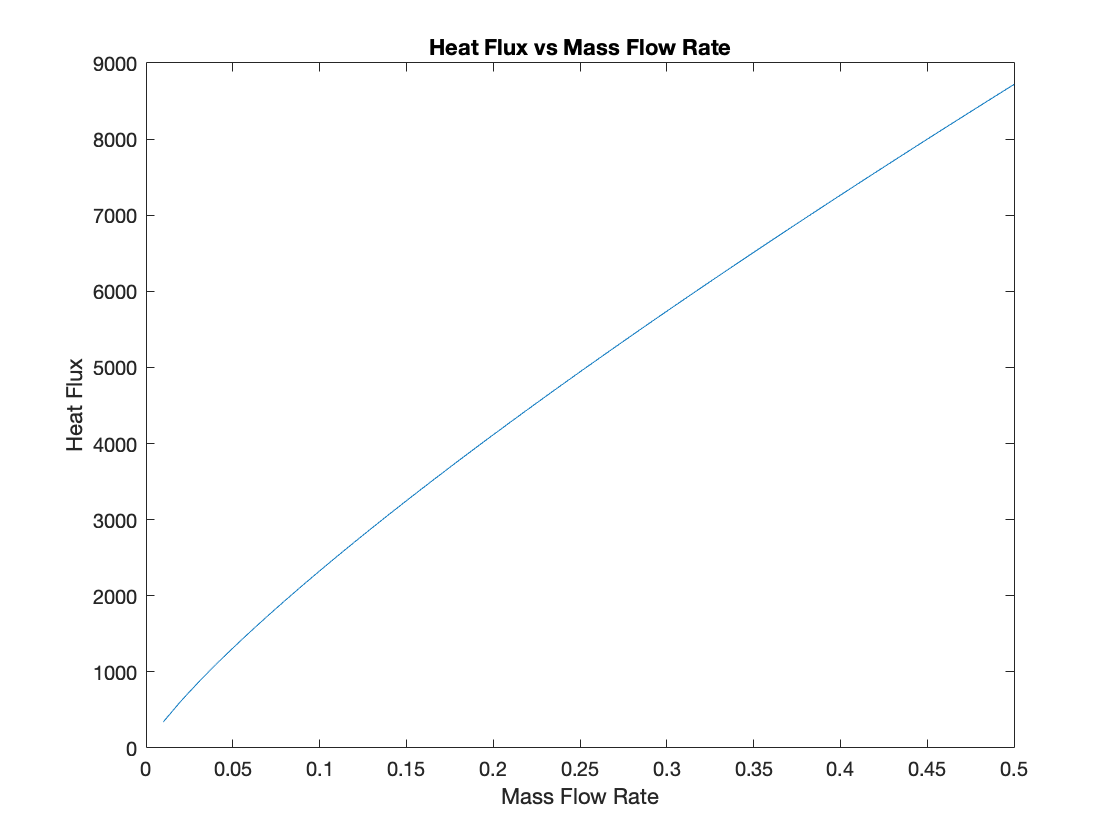

for j = 1:50
    m = 0.01*j;
    D = 0.01;
    N = 10;
    L = 0.6;
    Tcp = 32;
    myu = 1080*10^-6;
    re = 4*m/(pi*D*myu);
    pr = 7.56;
    k = 0.598;
    h = 0.023*k*(re^0.8)*(pr^0.4)/D;
    cp = 4184;
    Ti = 7;
 
    for i = 1:12
        x = i*0.05;
        To(i) = Tcp - (Tcp - Ti)*(exp((-pi*D*x*h)/(m*cp)));
    end

    q(j) = m*cp*(To(1,12)-Ti);
end
k = [0.01:0.01:0.50];
z = [0.05:0.05:0.6];
plot(k,q)
xlabel('Mass Flow Rate')
ylabel('Heat Flux')
title('Heat Flux vs Mass Flow Rate')

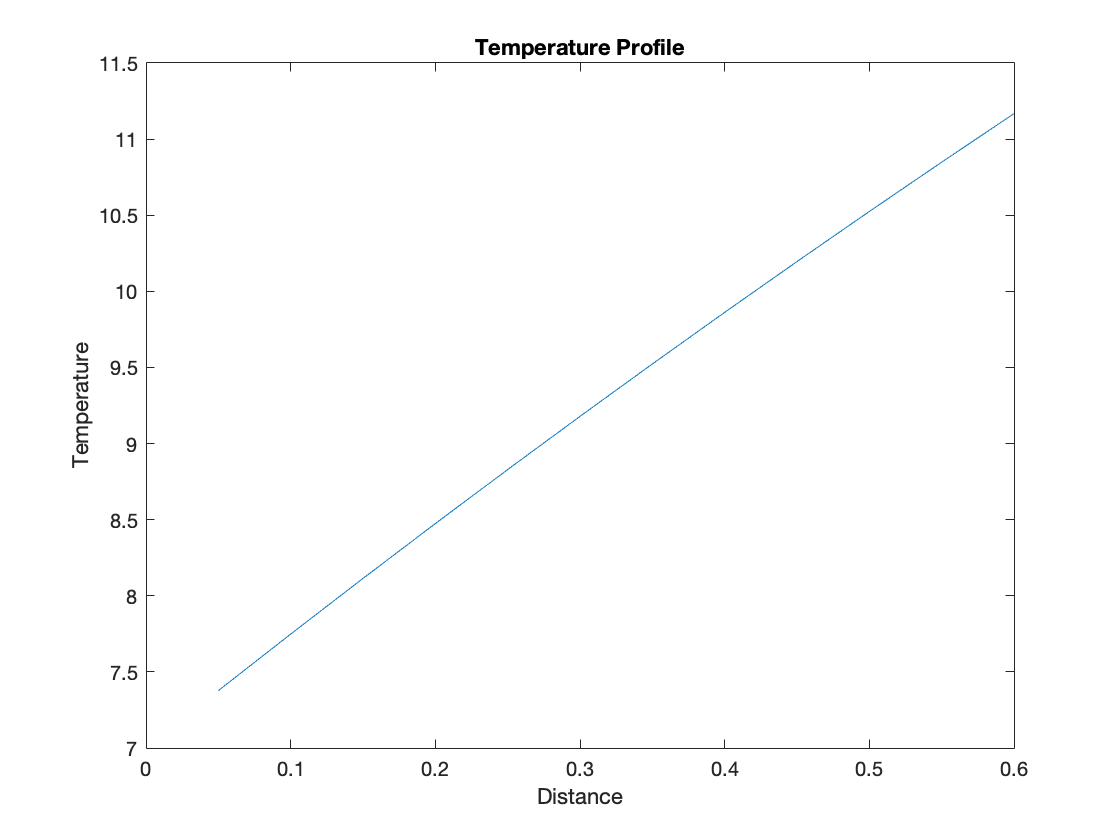

plot(z,To)
xlabel('Distance')
ylabel('Temperature')
title('Temperature Profile')


%Assuming Heat is needed to be taken out sinodially
mdl = fitlm(k',q')

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     635.35     43.398     14.64    2.5041e-19
    x1               16637     148.12    112.32    8.8725e-60


Number of observations: 50, Error degrees of freedom: 48
Root Mean Squared Error: 151
R-squared: 0.996,  Adjusted R-Squared: 0.996
F-statistic vs. constant model: 1.26e+04, p-value = 8.87e-60

coeff = mdl.Coefficients.Estimate

coeff = 	1.0e+04 *

    0.0635
    1.6637


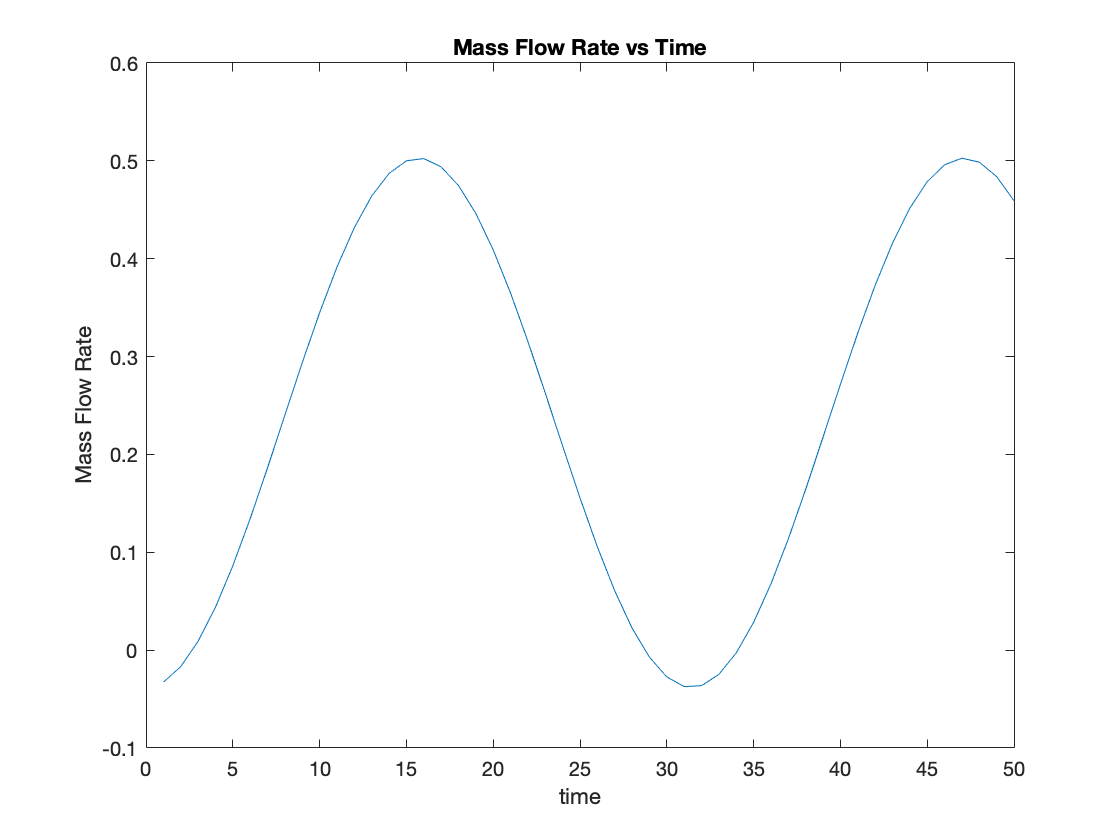

for t= 1:50
    w = 1/10;
    Qo = 9000;
    Q = Qo*(sin(w*t))^2;
    m0(t) = Q/(1.6637*10^4) - 0.0635/1.6637;
end
f = [1:50];
plot(f,m0)
xlim([0.0 50.0])
ylim([-0.100 0.600])
title('Mass Flow Rate vs Time')
xlabel('time')
ylabel('Mass Flow Rate')